# **Part 1:Rotation**

# Exercise 1.1

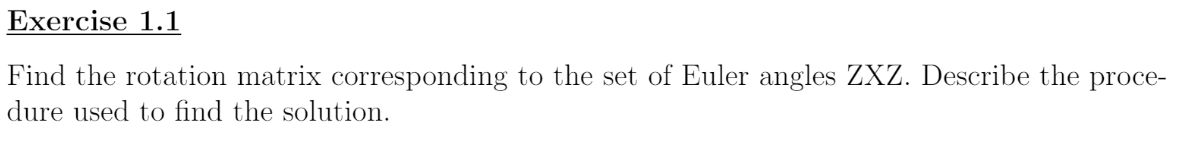

syms theta alpha beta phi
zrot=[cos(theta) -sin(theta) 0;sin(theta) cos(theta) 0;0 0 1]% rotation around z

$$zrot = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

xrot=[1 0 0;0 cos(alpha) -sin(alpha);0 sin(alpha) cos(alpha)]% rotation around x

$$xrot = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\alpha \right) & -\sin\left(\alpha \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

yrot=[cos(beta) 0 sin(beta);0 1 0;-sin(beta) 0 cos(beta)]% rotation around y

$$yrot = \left(\begin{array}{ccc} \cos\left(\beta \right) & 0 & \sin\left(\beta \right)\\ 0 & 1 & 0\\ -\sin\left(\beta \right) & 0 & \cos\left(\beta \right) \end{array}\right)$$

zrot2=[cos(phi) -sin(phi) 0;sin(phi) cos(phi) 0;0 0 1]% rotation around z

$$zrot2 = \left(\begin{array}{ccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


Eul=simplify(zrot*xrot*zrot2)

$$Eul = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\theta \right)-\cos\left(\alpha \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right) & -\cos\left(\theta \right)\,\sin\left(\varphi \right)-\cos\left(\alpha \right)\,\cos\left(\varphi \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\theta \right)+\cos\left(\alpha \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\alpha \right)\,\cos\left(\varphi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\theta \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right)\\ \sin\left(\alpha \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

# Exercise 1.2

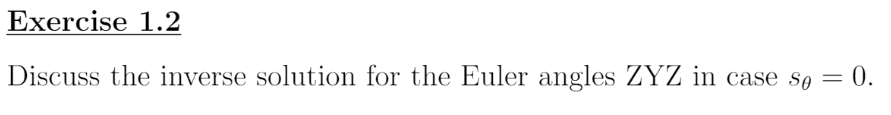

# Exercise 1.3

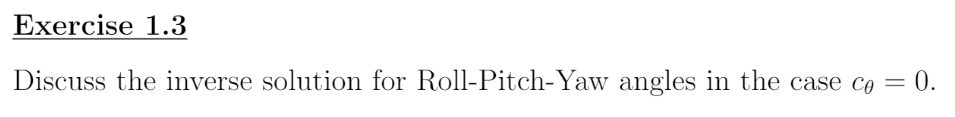

# Exercise 1.4

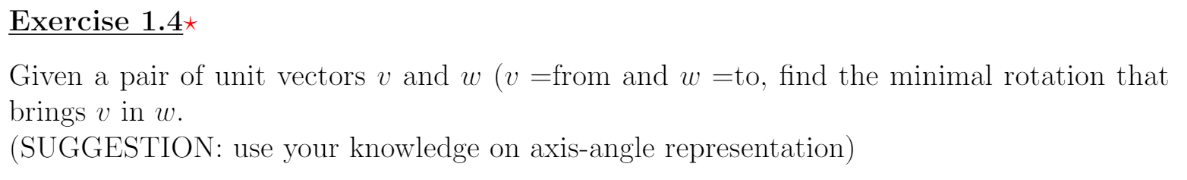

# Exercise 1.5

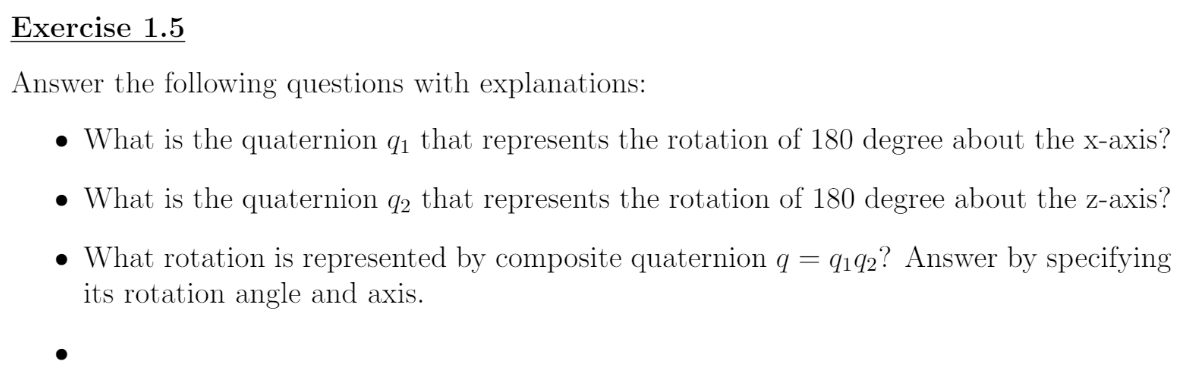

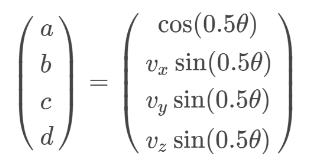

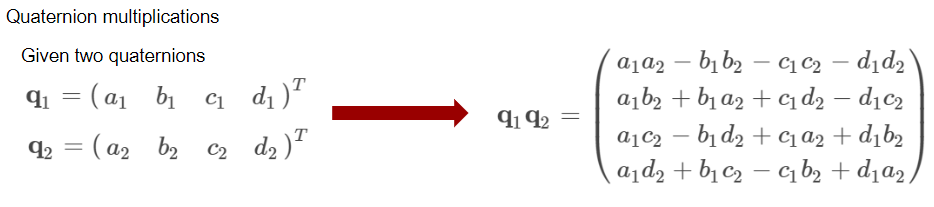

vx = 1;
vy = 0;
vz = 0;
theta = deg2rad(180);

q1 = [cos(0.5*theta);vx*sin(0.5*theta);vy*sin(0.5*theta);vz*sin(0.5*theta)];
q1

q1 =     0.0000
    1.0000
         0
         0


%%%%%%%%
vx = 0;
vy = 0;
vz = 1;
theta = deg2rad(180);

q2 = [cos(0.5*theta);vx*sin(0.5*theta);vy*sin(0.5*theta);vz*sin(0.5*theta)];
q2

q2 =     0.0000
         0
         0
    1.0000


%%%%%%%%
q = qMultiply(q1,q2);

q =     0.0000
    0.0000
   -1.0000
    0.0000


q

# Exercise 1.6

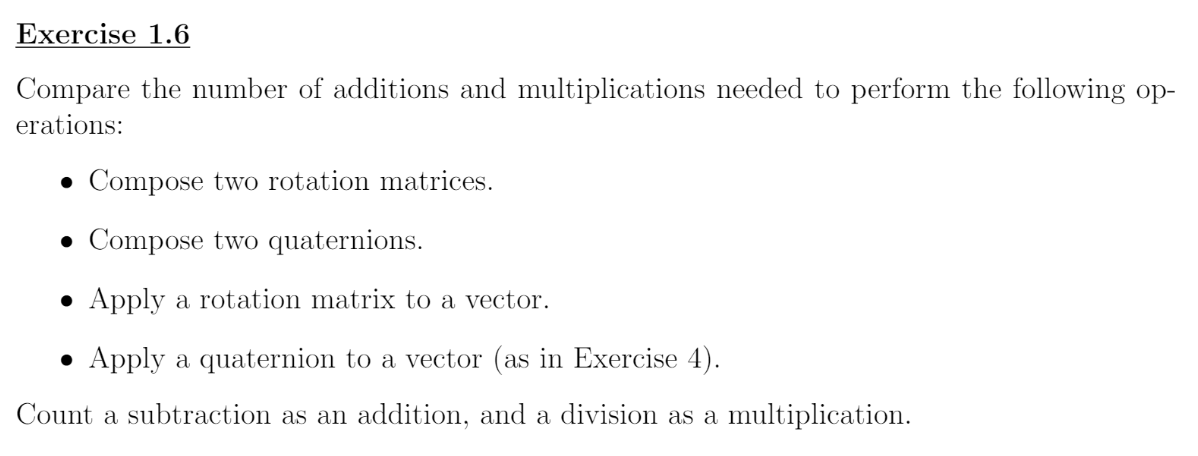

syms theta alpha beta phi
zrot=[cos(phi) -sin(phi) 0;sin(phi) cos(phi) 0;0 0 1]% rotation around z

$$zrot = \left(\begin{array}{ccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

yrot=[cos(theta) 0 sin(theta);0 1 0;-sin(theta) 0 cos(theta)]% rotation around y

$$yrot = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

xrot=[1 0 0;0 cos(alpha) -sin(alpha);0 sin(alpha) cos(alpha)]% rotation around x

$$xrot = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\alpha \right) & -\sin\left(\alpha \right)\\ 0 & \sin\left(\alpha \right) & \cos\left(\alpha \right) \end{array}\right)$$

zrot*xrot(:,1)

$$ans = \left(\begin{array}{c} \cos\left(\varphi \right)\\ \sin\left(\varphi \right)\\ 0 \end{array}\right)$$

zrot*xrot(:,2)

$$ans = \left(\begin{array}{c} -\cos\left(\alpha \right)\,\sin\left(\varphi \right)\\ \cos\left(\alpha \right)\,\cos\left(\varphi \right)\\ \sin\left(\alpha \right) \end{array}\right)$$

zrot*xrot(:,3)

$$ans = \left(\begin{array}{c} \sin\left(\alpha \right)\,\sin\left(\varphi \right)\\ -\cos\left(\varphi \right)\,\sin\left(\alpha \right)\\ \cos\left(\alpha \right) \end{array}\right)$$

xrot*yrot

$$ans = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ \sin\left(\alpha \right)\,\sin\left(\theta \right) & \cos\left(\alpha \right) & -\sin\left(\alpha \right)\,\cos\left(\theta \right)\\ -\cos\left(\alpha \right)\,\sin\left(\theta \right) & \sin\left(\alpha \right) & \cos\left(\alpha \right)\,\cos\left(\theta \right) \end{array}\right)$$

function q = qMultiply(q1,q2)
%UNTITLED Summary of this function goes here
%   Detailed explanation goes here
a1 = q1(1);
b1 = q1(2);
c1 = q1(3);
d1 = q1(4);
a2 = q2(1);
b2 = q2(2);
c2 = q2(3);
d2 = q2(4);
q = [a1*a2-b1*b2-c1*c2-d1*d2;
    a1*b2+b1*a2+c1*d2-d1*c2;
    a1*c2-b1*d2+c1*a2+d1*b2;
    a1*d2+b1*c2-c1*b2+d1*a2];
end